# Simple equilibriuim reaction

Ao = 0.25;
Bo = 0.1;
kf = 2;
kb = 1;

t = 0:0.1;1;

r1 = (1/(kf+kb))*(kb+kf*exp(-(kf+kb)*t));
r2 = (kf/(kf+kb))*(1-exp(-(kf+kb)*t));

A = Ao*r1 + Bo*r2;
B = Ao*r2 + Bo*r1;

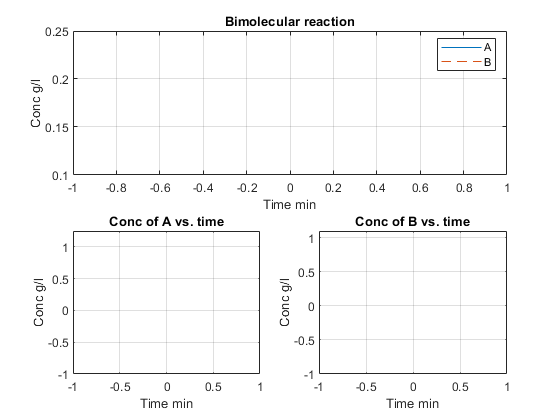

subplot(2,2, [1,2])
plot(t,A,t,B,'--')
xlabel('Time min')
ylabel('Conc g/l')
title('Bimolecular reaction')
legend('A', 'B')
grid

subplot(2,2,3)
plot(t,A)
xlabel('Time min')
ylabel('Conc g/l')
title('Conc of A vs. time')
grid

subplot(2,2,4)
plot(t,B)
xlabel('Time min')
ylabel('Conc g/l')
title('Conc of B vs. time')
grid